# Live Script to Illustrate Model Tracer Diagnostics using a Box Model

Thomas Haine (Thomas.Haine@jhu.edu) Jan '22, Jul '23 based on [Haine & Hall (2002)](https://journals.ametsoc.org/view/journals/phoc/32/6/1520-0485_2002_032_1932_agttwm_2.0.co_2.xml) box model.

## Housekeeping

clear
close all
more off
path(path,'~/OneDrive - Johns Hopkins/Documents/MATLAB/tools/tracer/') ;

## Set up box model flow

% Define flow. 
boxModel.flow.S = 20.0 ;            % North Atlantic sinking [Sv]
boxModel.flow.I = 10.0 ;            % Intermediate outflow [Sv]
boxModel.flow.d =  5.0 ;            % Mixing flux [Sv]
boxModel.volume = 300 ;             % Volume of each box [Sv.yr]
boxModel.sfcExchange = [20 10 0 0 0 0 0 0 0] ;      % Surface exchange rate [Sv]
boxModel = build_boxModel(boxModel) ;

% Set up time vector and time increment.
boxModel.dt   = 0.25 ;             % years
boxModel.taus = 0:boxModel.dt:2000 ;

## Plot figure of flow

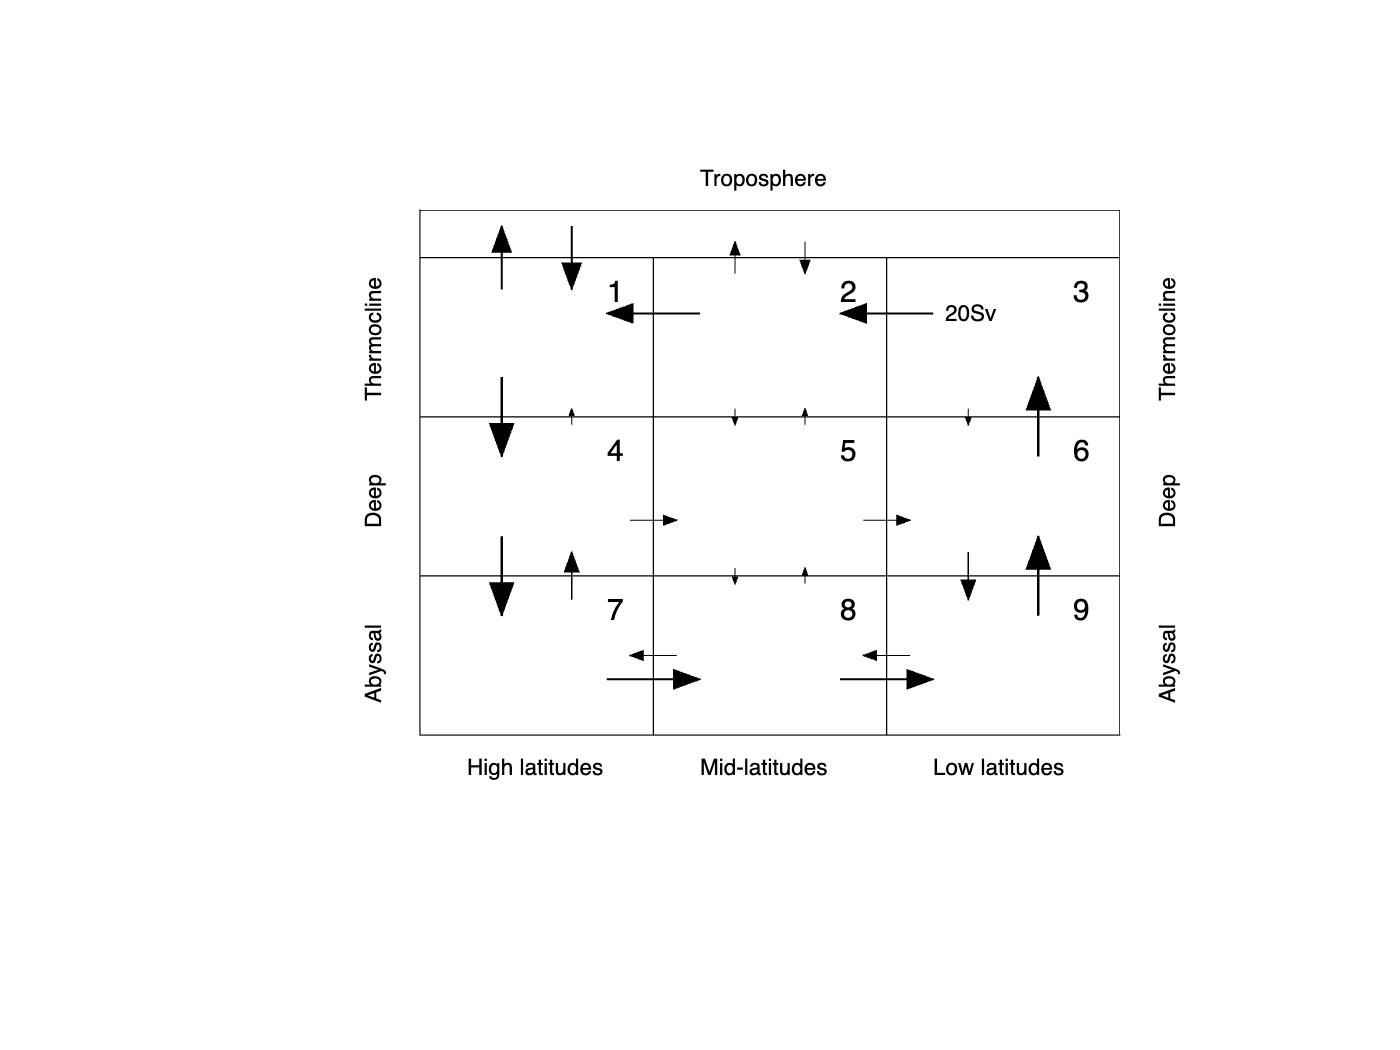

plot_boxModel(boxModel) ;

## Compute Green's function, boundary propagator, and adjoint boundary propagator, plus other theoretical timescale diagnostics

Solution = build_GreensFns(boxModel) ;

 Build Greens functions and related diagnostics...done.


test_GreensFns(boxModel,Solution)


 Test Green's function properties with numerical threshold of [1.00e-03],
                                  and analytical threshold of [2.22e-13].
 Analytic  check on global forward TTD normalisation...PASSED.
 Analytic  check on global adjoint TTD normalisation...PASSED.
 Numerical check on [fwd] TTD normalization, watermass properties, tail asymptotes, mean ages, and widths...PASSED.
 Numerical check on [adj] TTD normalization, watermass properties, tail asymptotes, mean ages, and widths...PASSED.
 Analytic  check on RTD normalisation...PASSED.
 Numerical check on RTD water mass fractions...PASSED.
 Numerical check on RTD mean residence times...PASSED.
 Numerical check on RTD widths...PASSED.
 Numerical check on RTD tail asymptotes...PASSED.
 Numerical check on path density sum...PASSED.
 Numerical check on path density tail asymptotes...PASSED.
 Analytic  check on steady state forward ideal age calculation with analytical threshold of [2.22e-11]...PASSED.
 Analytic  check on stead

## Plot figure of Green's function and boundary propagators, plus other theoretical timescale diagnostics


 Plot Greens functions and related diagnostics...

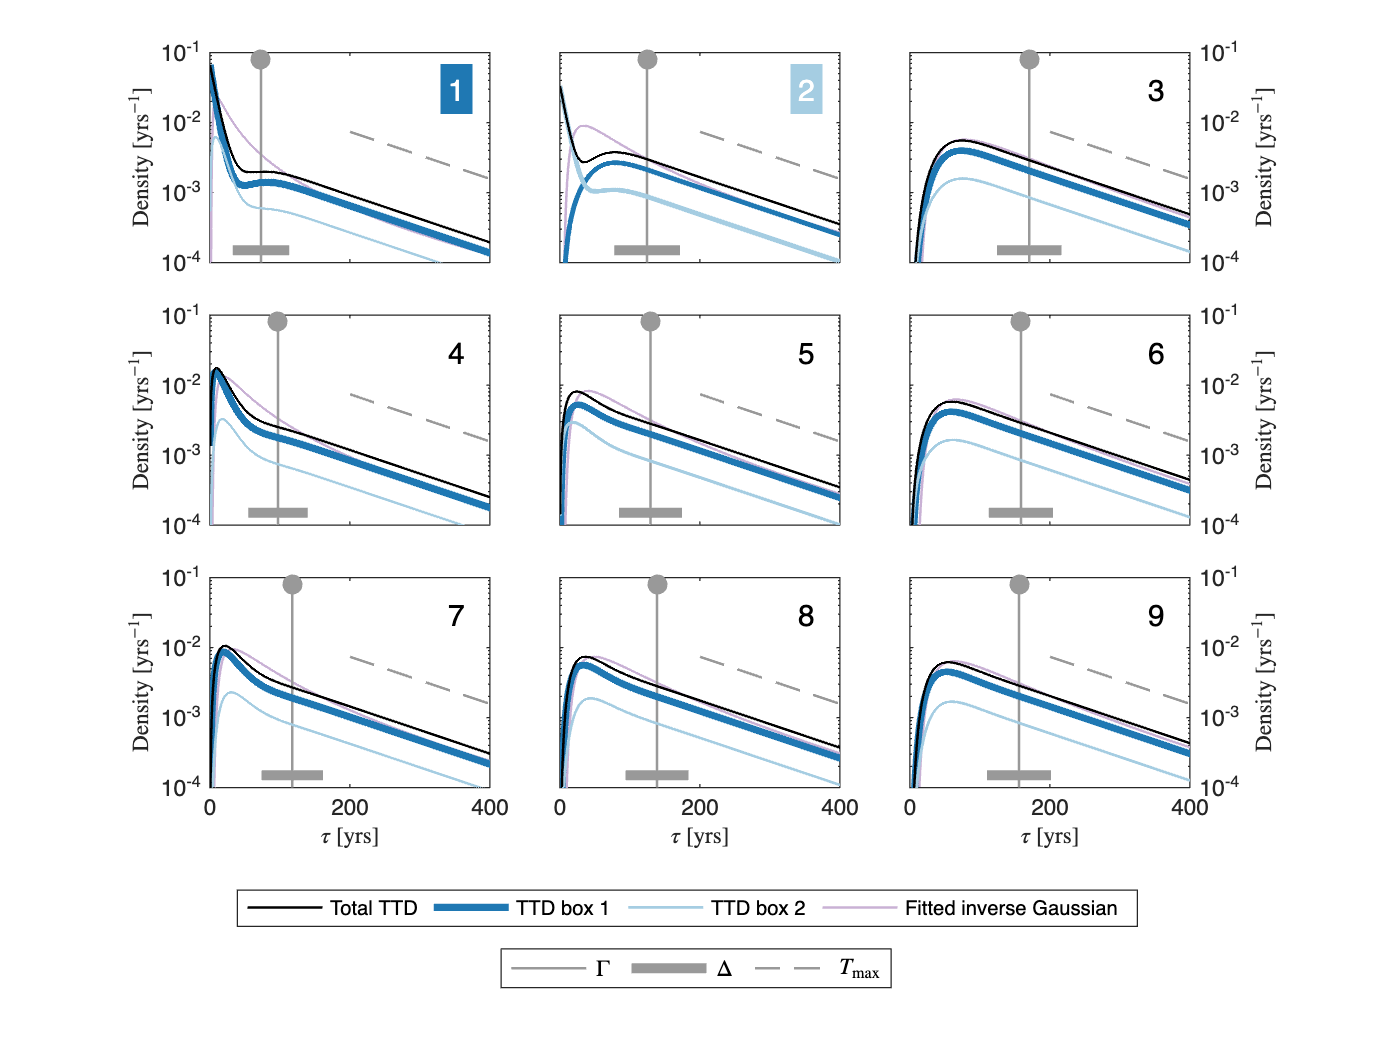

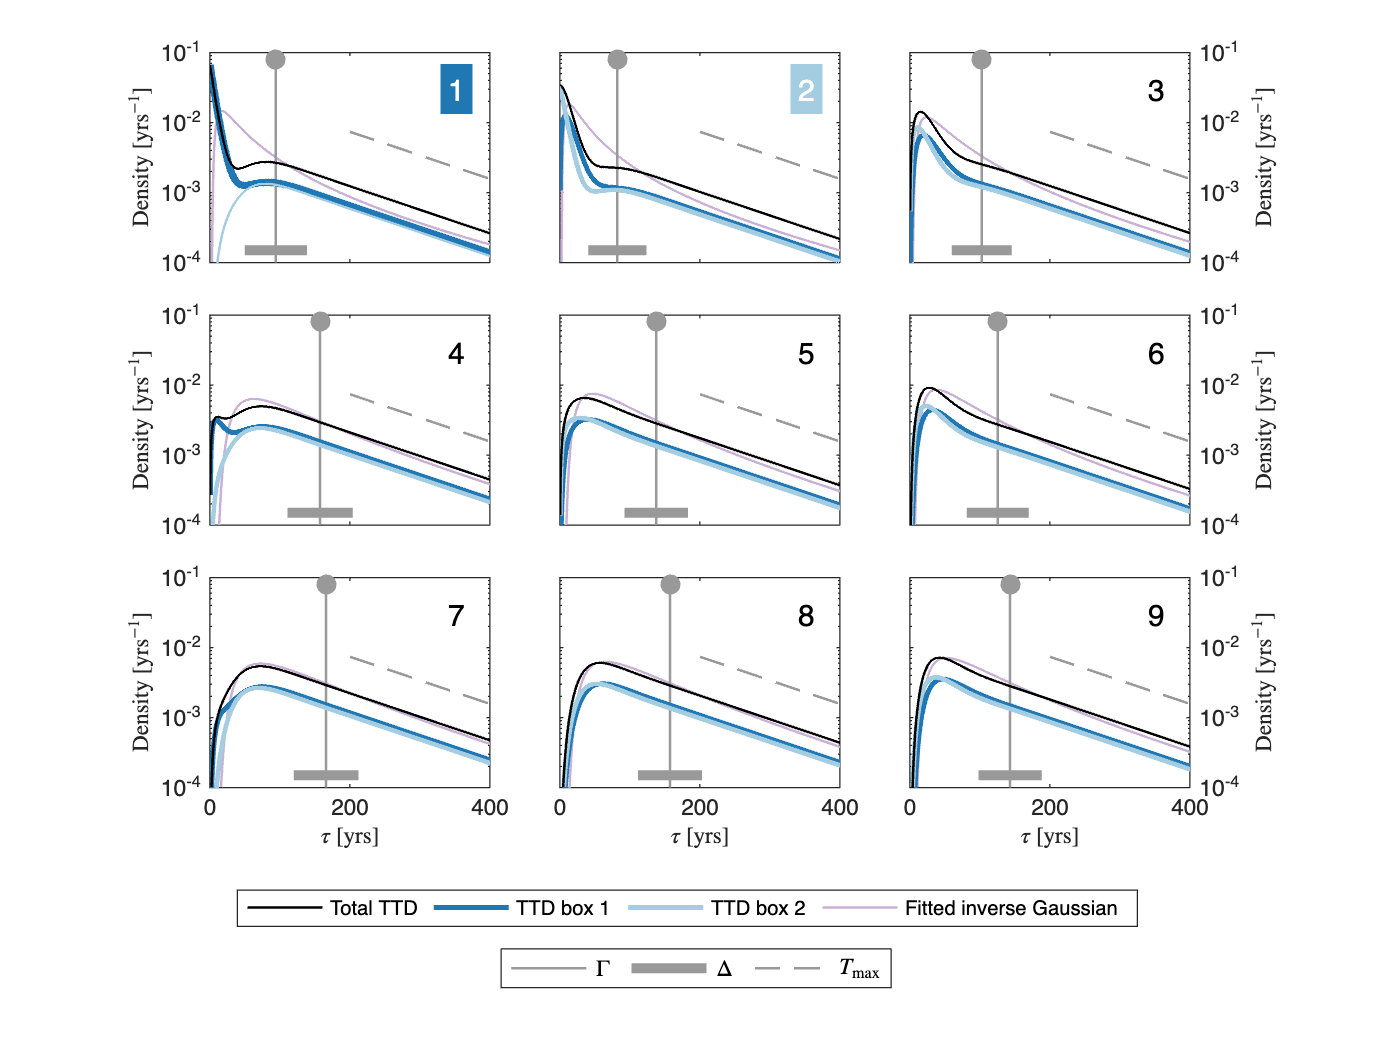

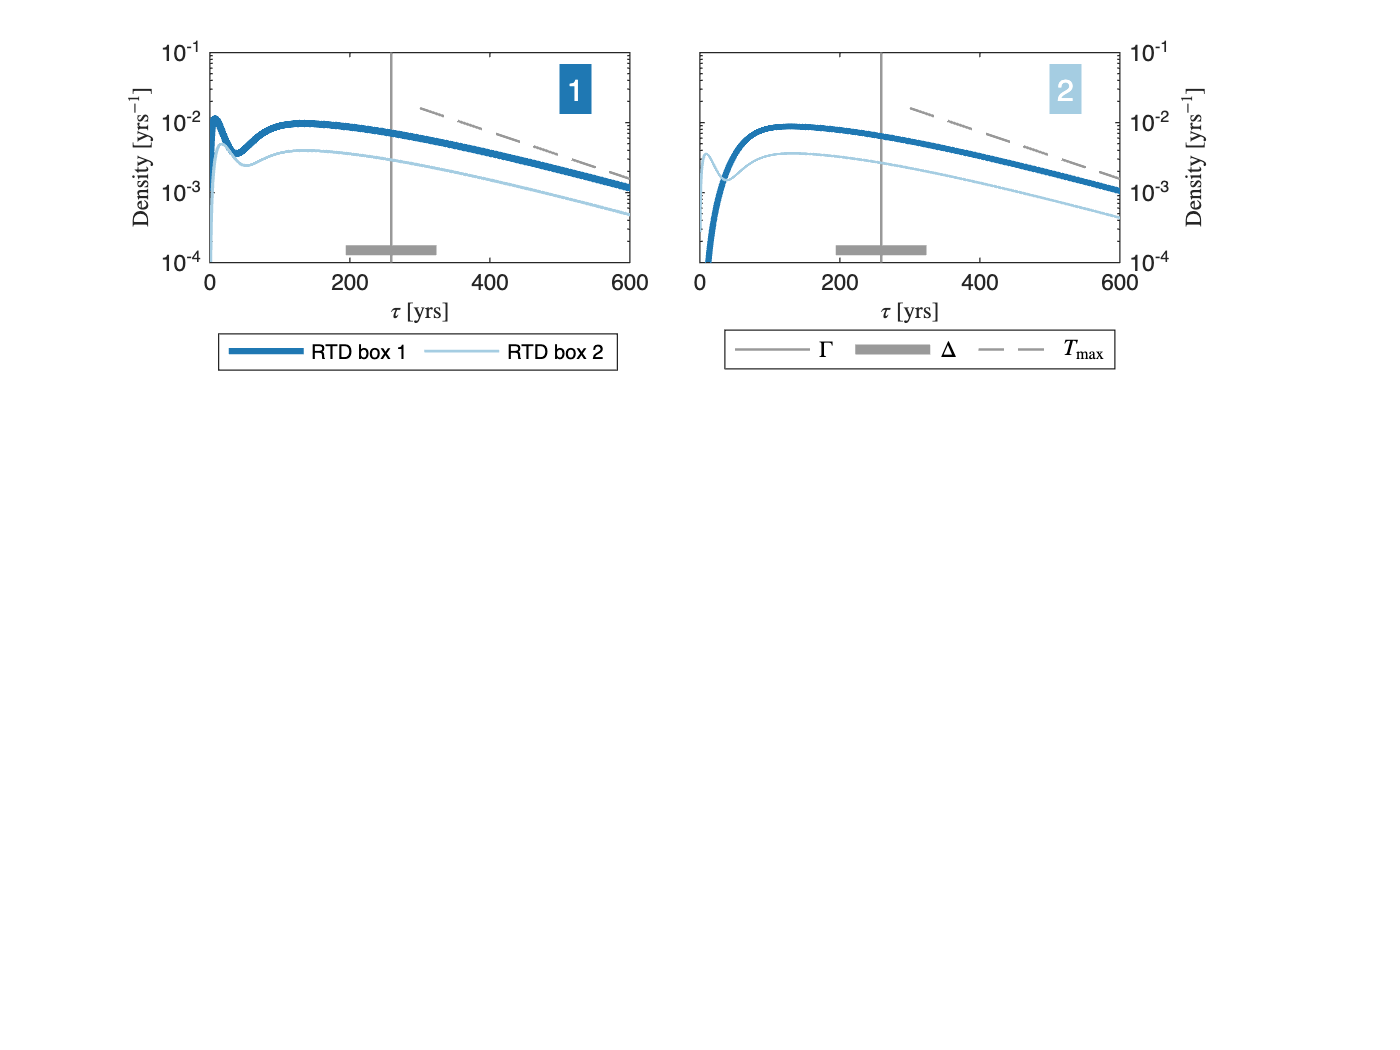

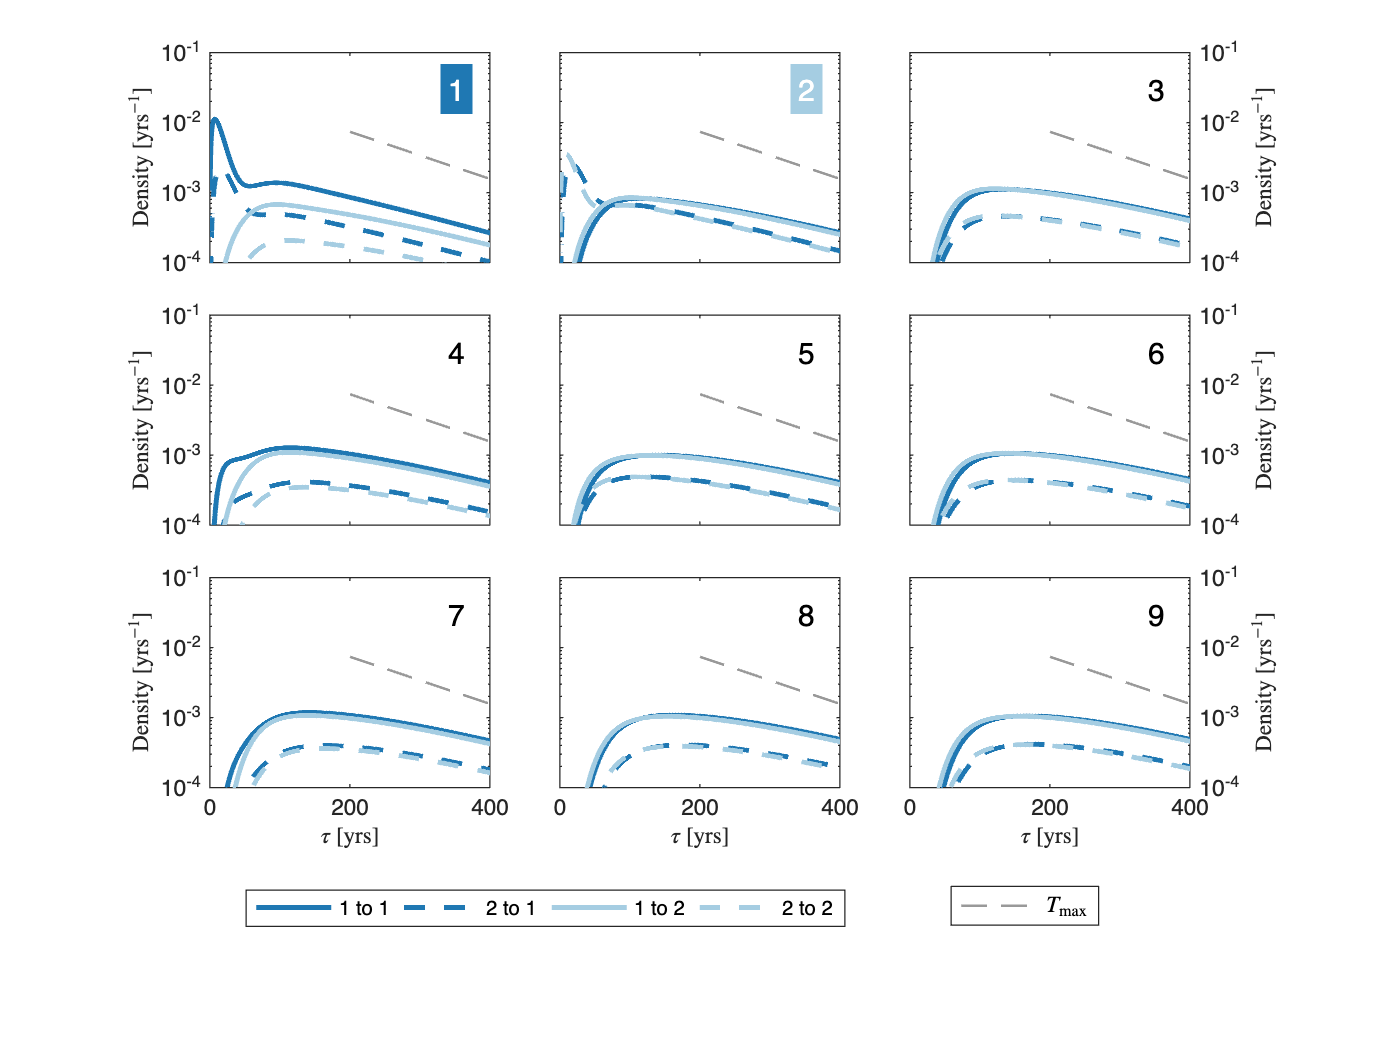

done.


plot_GreensFns(boxModel,Solution) ;

## Compute concentration histories for CFC-11, CFC-12, SF6, 39Ar, 129I and compute various tracer ages

Tracer = build_tracers(boxModel) ;

 Load tracer history file...done.
 Compute concentration history for [CFC11]...box 2 to box 1 source ratio = [0.75]...done.
 Compute concentration history for [CFC12]...box 2 to box 1 source ratio = [0.75]...done.
 Compute concentration history for [SF6]...box 2 to box 1 source ratio = [0.75]...done.
 Compute concentration history for [Ar39]...box 2 to box 1 source ratio = [1.00]...done.
 Compute concentration history for [I129]...box 2 to box 1 source ratio = [0.25]...done.

 Test steady state theory with numerical threshold of [1.00e-03],
 Analytic check on steady state for Ar39...PASSED. Speed up is [  2102]x for mean difference of [  1e-07]%.



## Plot figure of concentration histories, tracer ages, and theoretical timescale diagnostics

 Plot tracer sources, concentrations, and ages...
 Plotting [CFC11] ages for [2015].
 Plotting [CFC12] ages for [2015].
 Plotting [SF6] ages for [2015].
 Plotting [Ar39] ages for [2015].


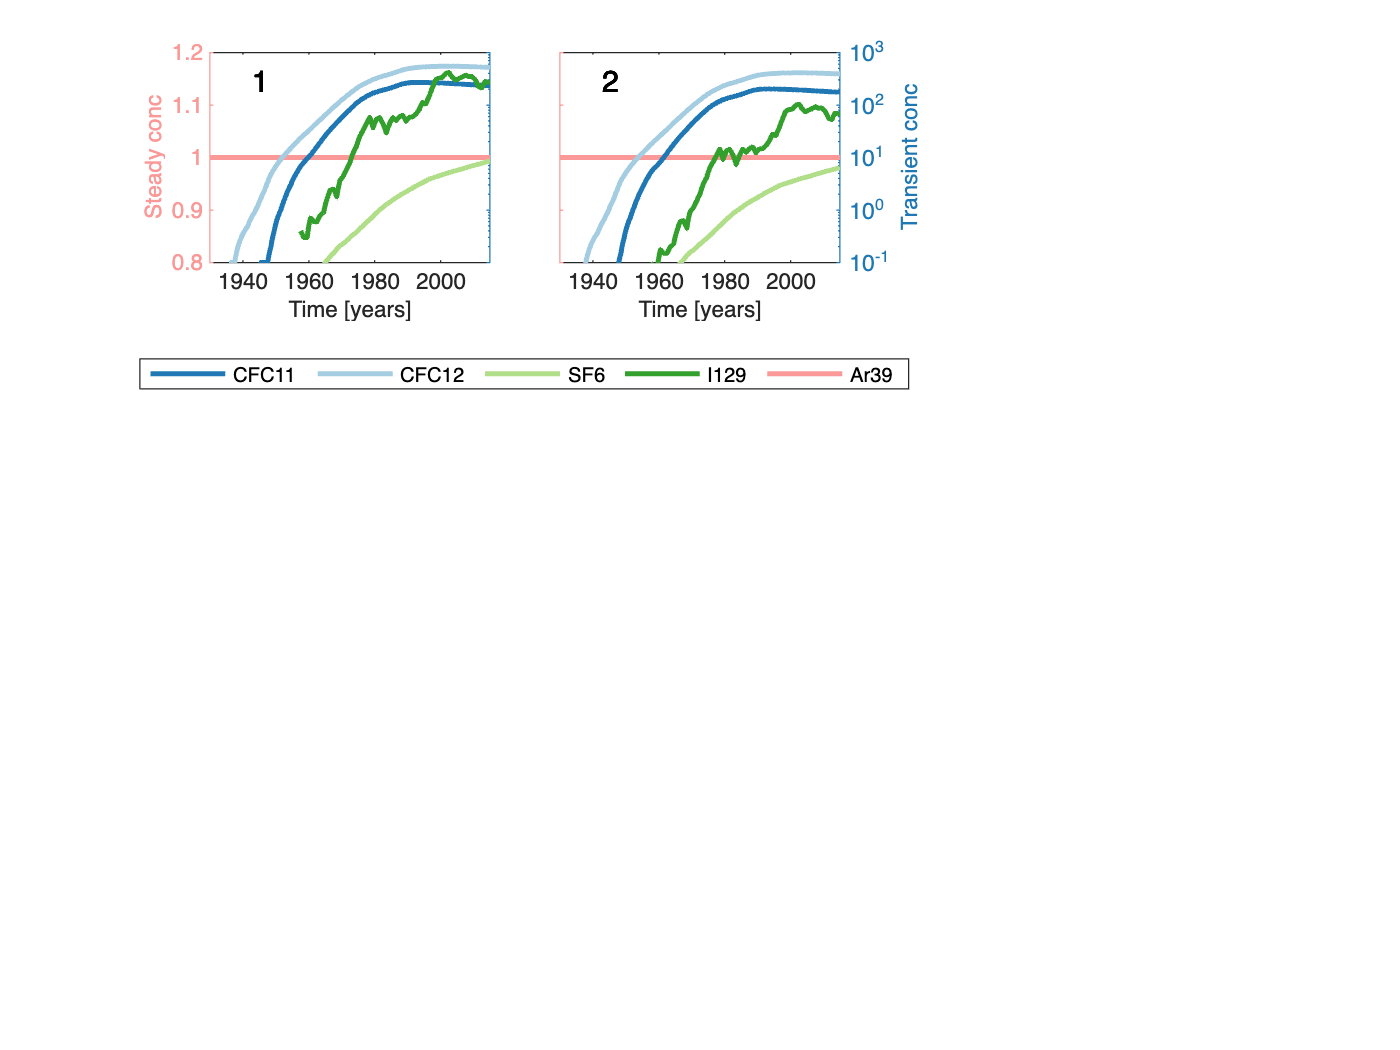

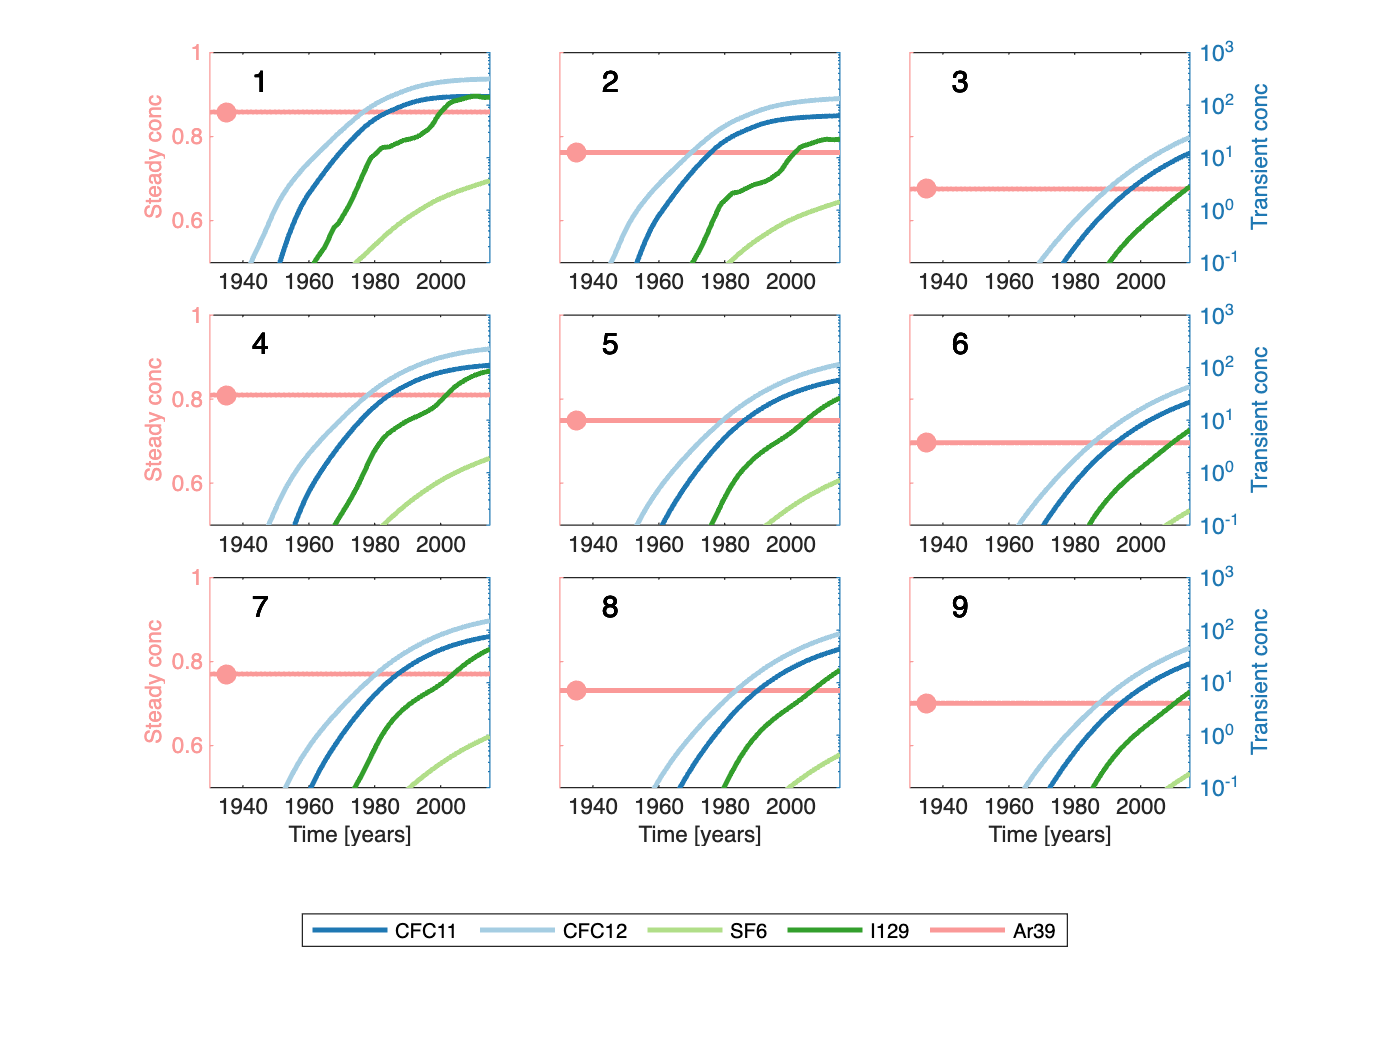

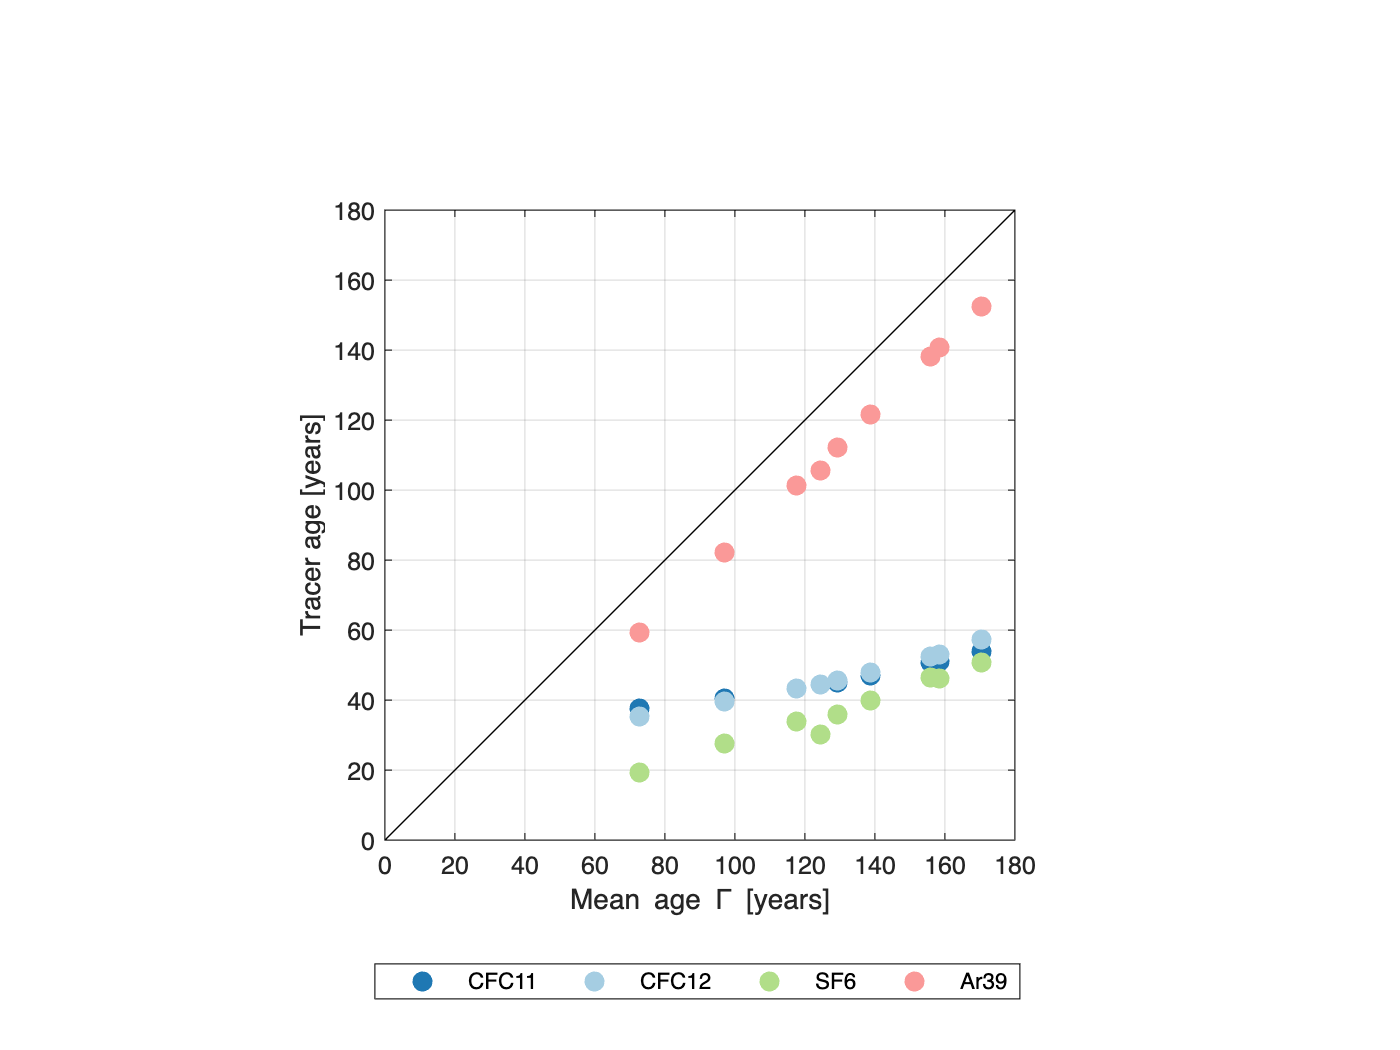

plot_tracers(Tracer,Solution) ;